# ระบบหุ่นยนต์ pick-and-place

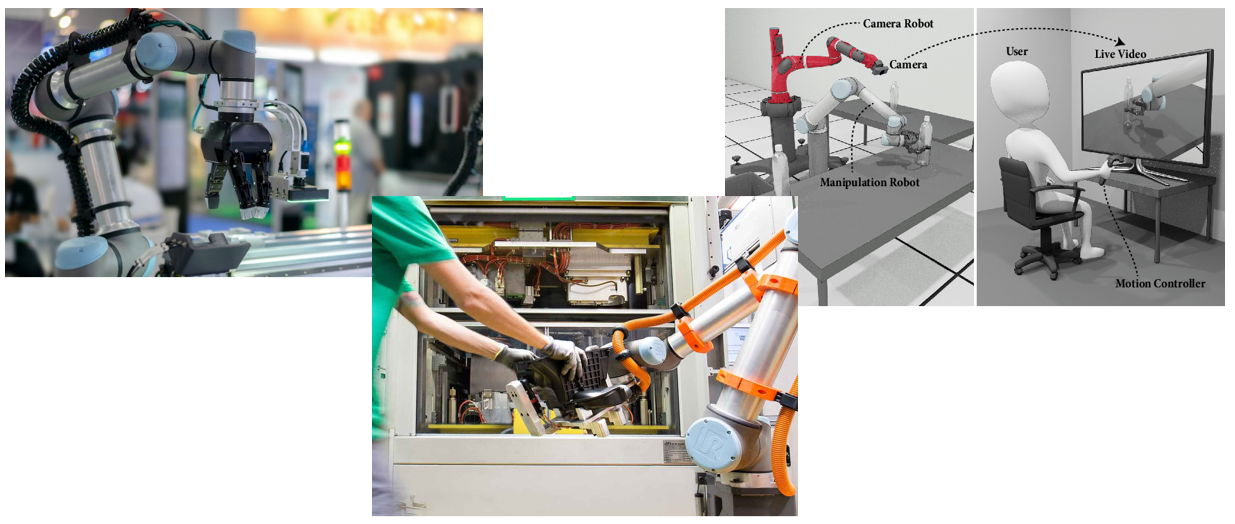

### องค์ประกอบของแขนกล

A rigid body tree is made up of rigid bodies ([`rigidBody`](https://www.mathworks.com/help/robotics/ref/rigidbody.html)) that are attached via joints ([`rigidBodyJoint`](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.html)). Each rigid body has one joint, which defines the motion of that rigid body relative to its parent. These joints allow the following motion, depending on their type:

- `'fixed'` — No motion. Body is rigidly connected to its parent.

- `'revolute'` — Rotational motion only. Body rotates around this joint relative to its parent. Position limits define the minimum and maximum angular position in radians around the axis of motion.

- `'prismatic'` — Translational motion only. The body moves linearly relative to its parent along the axis of motion.

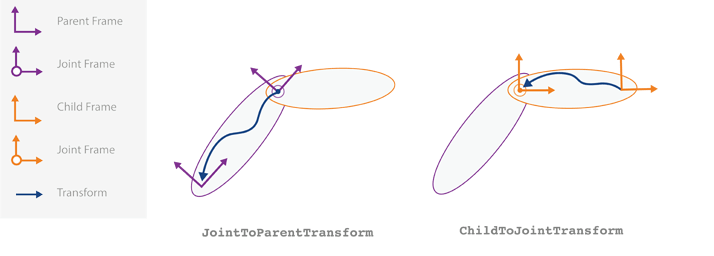

#### อ้างอิง

[Rigid Body Tree Robot Model - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/robotics/ug/rigid-body-tree-robot-model.html)

### การใช้ MATLAB กับแขนกล

The Robotics System Toolbox lets you co-simulate your robot applications by connecting directly to the Gazebo robotics simulator. To verify your design on hardware, you can connect to robotics platforms such as Kinova Gen3 and Universal Robots UR series robots and generate and deploy code (with MATLAB® Coder™ or Simulink® Coder).

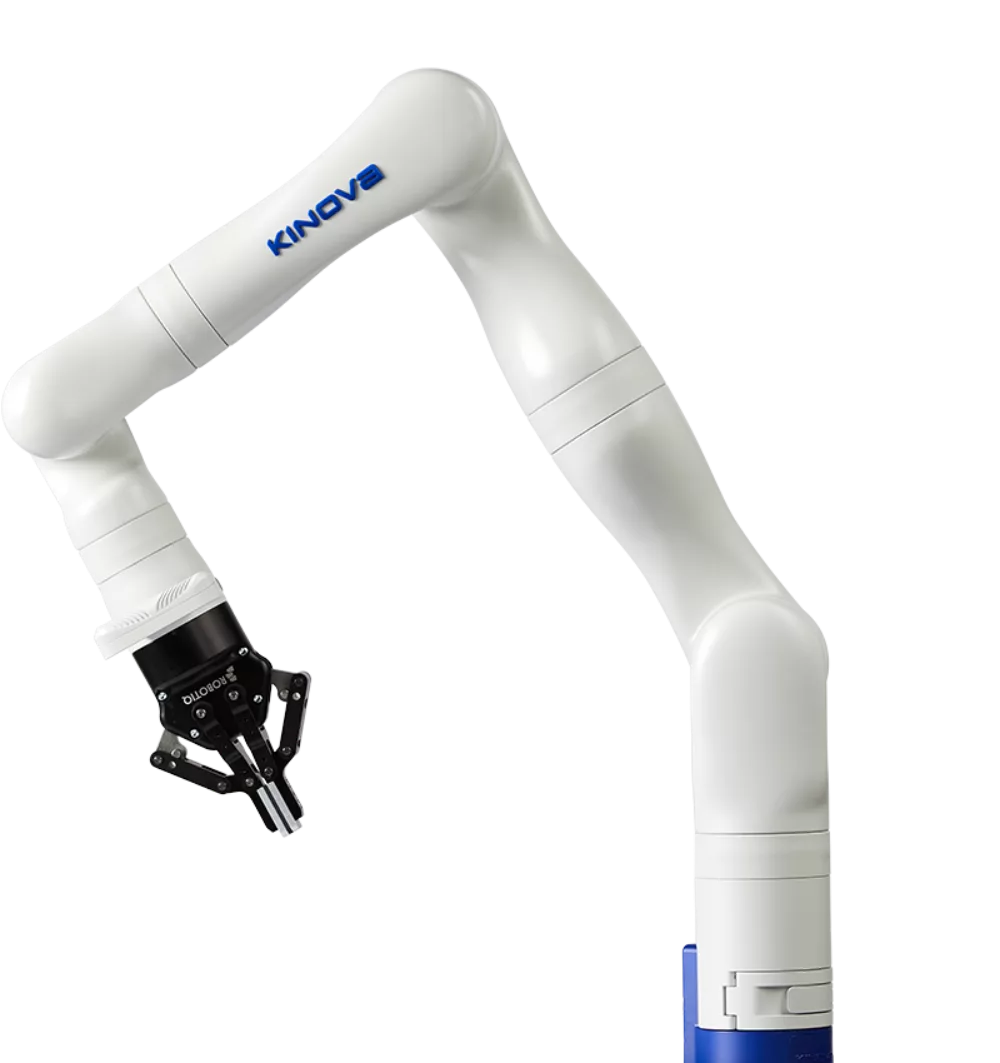  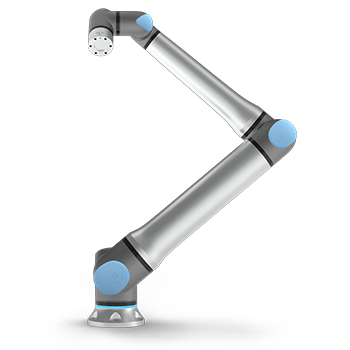

Robot models simulate the kinematic and dynamic properties of manipulator robots and other rigid body systems. The models are [`rigidBodyTree`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html) objects containing [`rigidBody`](https://www.mathworks.com/help/robotics/ref/rigidbody.html) and [`rigidBodyJoint`](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.html) elements with joint transformations and inertial properties. Access predefined models for certain commercial robots, such as KINOVA™ and KUKA™, using the [`loadrobot`](https://www.mathworks.com/help/robotics/ref/loadrobot.html) function.

robot = loadrobot("universalUR10");

The `interactiveRigidBodyTree` object creates a figure that displays a robot model using a [`rigidBodyTree`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html) object and enables you to directly modify the robot configuration using an interactive marker. The `rigidBodyTree` object defines the geometry of the different connected rigid bodies in the robot model and the joint limits for these bodies.

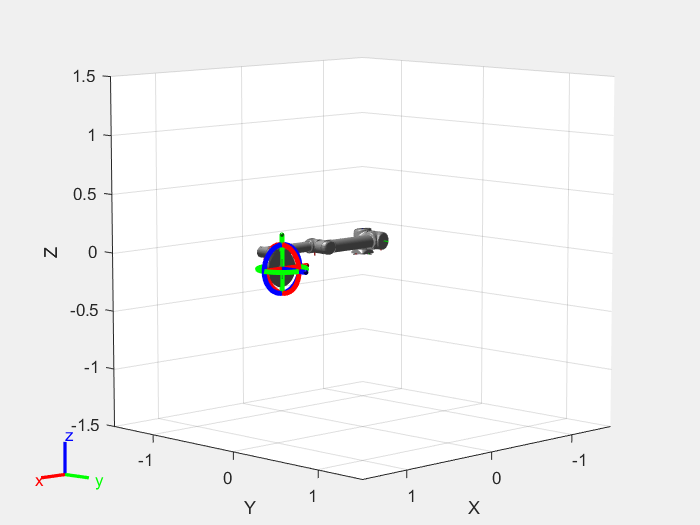

viztree = interactiveRigidBodyTree(robot);

#### อ้างอิง

[Robot Models - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/robotics/robot-models.html)

[Interact with rigid body tree robot models - MATLAB (mathworks.com)](https://www.mathworks.com/help/robotics/ref/interactiverigidbodytree.html)

[Robot Manipulator Support from Robotics System Toolbox - Hardware Support - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/hardware-support/robot-manipulator.html)

### ศึกษาตัวอย่าง

This example shows how to setup an end-to-end pick and place workflow for a robotic manipulator like the KINOVA® Gen3. The pick-and-place workflow implemented in this example can be adapted to different scenarios, planners, simulation platforms, and object detection options. This example uses a Stateflow chart to schedule tasks in the example.

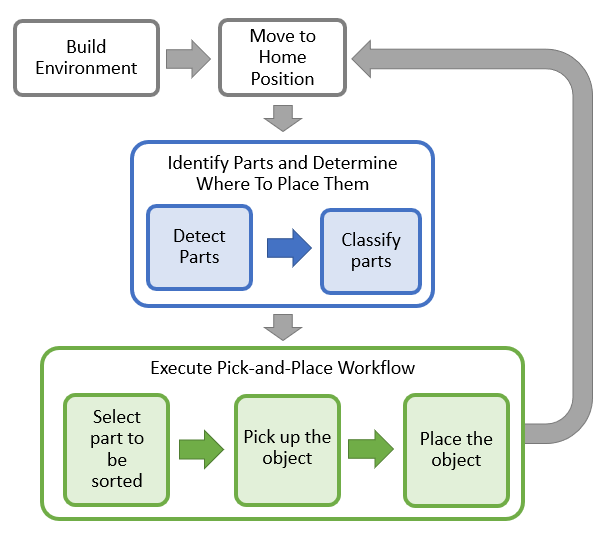

openExample('robotics/PickAndPlaceWorkflowUsingStateflowForMATLABExample')

[Pick-and-Place Workflow Using Stateflow for MATLAB - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/robotics/ug/pick-and-place-workflow-using-stateflow.html)

### ขั้นที่ 1 เตรียมโมเดลของแขนกลและสภาพแวดล้อม

% Load model of kinova Gen 3 robot model
load('KINOVAGen3GripperColl.mat'); 
joint_states = homeConfiguration(robot);
parts = {[0.4 -0.1 0.26], [0.5 -0.15 0.26], [0.52 0 0.26]};
colors = ["r", "g", "b"];
env = tgrCreateEnv(parts, colors);

'tgrCreateEnv' is not found in the current folder or on
the MATLAB path, but exists in:
    C:\Users\oatza\OneDrive\เดสก์ท็อป\โฟลเดอร์ใหม่ (2)

Change the MATLAB current folder or add its folder to
the MATLAB path.

robotCell = tgrRobotEnvInteraction(robot, joint_states, "gripper", env);
robotCell.visualizeStation();
robotCell.visualizeParts();

### ขั้นที่ 2 ศึกษา joint state และ task state

Homogeneous Transformation Matrix combines a translation and rotation into one matrix. It can be used to express the configuration (position and orientation) of a frame relative to a fixed frame. 

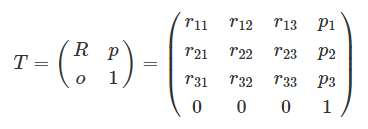

The advantage of adopting the 4×4 matrices to implicitly represent the configuration of a robot is the simple algebraic calculations that can be used to work with these matrices. 

Suppose an arm-mounted mobile robot [X-Terrabot ](https://robots.ros.org/x-terrabot/)is moving in a room and wants to pick up an object with body frame {e} with its end-effector with the attached frame {c}. 

- A camera is fixed to the ceiling, and based on its measurements, the configuration of the frames attached to the wheeled platform {b} and the object frame {e} relative to the camera’s frame {d} are known.

- Using the arm’s joint angle measurements, Tbc is also known.

- The configuration of the camera frame {d} relative to the fixed-frame {a} is known in advance.

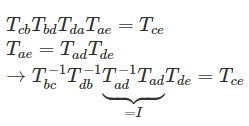

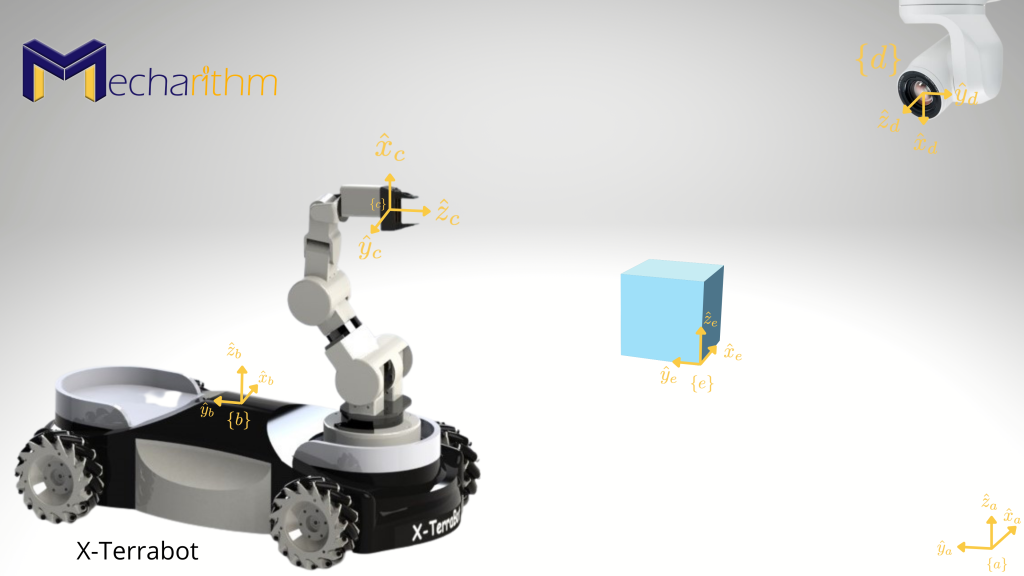

[Homogenous Transformation Matrices for Configurations in Robotics (mecharithm.com)](https://www.mecharithm.com/homogenous-transformation-matrices-configurations-in-robotics/)

[Coordinate Transformations in Robotics - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html)

% show original pose
task_states_0 = getTransform(robotCell.Robot, robotCell.CurrentJointConfig, robotCell.RobotEndEffector)

% try randomly move robot joints
for i = 1:100
    joint_states = joint_states + 0.01*rand(1,7);
    robotCell.moveJoints(joint_states);
    pause(0.1)
end
task_states_1 = getTransform(robotCell.Robot, robotCell.CurrentJointConfig, robotCell.RobotEndEffector)

### ขั้นที่ 3 ย้ายแขนกลมาที่ตำแหน่ง HOME

Inverse kinematics (IK) determines joint configurations of a robot model to achieve a desired end-effect position. Robot kinematic constraints are specified in the [`rigidBodyTree`](https://www.mathworks.com/help/releases/R2022a/robotics/ref/rigidbodytree.html) robot model based on the transformation between joints.

The `inverseKinematics` System object™ creates an inverse kinematic (IK) solver to calculate joint configurations for a desired end-effector pose based on a specified rigid body tree model. To compute joint configurations for a desired end-effector pose:

- Create the `inverseKinematics` object and set its properties.

- Call the object with arguments, as if it were a function.

`trvec2tform(`[`trvec`](https://www.mathworks.com/help/releases/R2022a/nav/ref/trvec2tform.html?overload=trvec2tform%20false&doclanguage=en&nocookie=true&prodfilter=ML%20SL%20AS%20BL%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20NN%20DS%20ET%20EC%20IT%20FI%20PO%20FL%20GD%20IA%20IP%20OT%20IC%20LP%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RQ%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20XP%20SR%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20WA%20WL&addons=mobilesensor%20armcortexm%20robotmanipulator%20raspberrypi%20usbwebcams%20arduinoio%20rtlsdrradio%20arduino%20nucleo%20raspberrypiio%20stmicroelectronicsstm32f4discovery&docviewer=helpbrowser&docrelease=R2022a&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DWI2CTB%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw%203p&snc=WRMVSD&container=jshelpbrowser#buog5np-trvec)`)` converts the Cartesian representation of a translation vector, `trvec`, to the corresponding homogeneous transformation, `tform`.

`axang2tform``(`[`axang`](https://www.mathworks.com/help/releases/R2022a/robotics/ref/axang2tform.html?searchHighlight=axang2tform&s_tid=doc_srchtitle#buoeipi-axang)`)` converts a rotation given in axis-angle form, `axang`, to a homogeneous transformation matrix, `tform`.

[Create inverse kinematic solver - MATLAB (mathworks.com)](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html)

robotCell.HomeRobotTaskConfig = trvec2tform([0.4, 0, 0.5])*axang2tform([0 1 0 pi]);
ik = inverseKinematics('RigidBodyTree', robotCell.Robot);
weights = ones(1, 6);
init_pose = robotCell.CurrentJointConfig;
[joint_sols, sols_info] = ik(robotCell.RobotEndEffector, robotCell.HomeRobotTaskConfig, weights, init_pose);
robotCell.moveJoints(joint_sols);

### ขั้นที่ 4 ปรับกลไกของ inverse kinematics

MATLAB® supports two algorithms for achieving an IK solution: the BFGS projection algorithm and the Levenberg-Marquardt algorithm. Both algorithms are iterative, gradient-based optimization methods that start from an initial guess at the solution and seek to minimize a specific cost function. If either algorithm converges to a configuration where the cost is close to zero within a specified tolerance, it has found a solution to the inverse kinematics problem. 

[Inverse Kinematics Algorithms - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/robotics/ug/inverse-kinematics-algorithms.html)

params.MaxIterations = 100;
ik = inverseKinematics('RigidBodyTree', robotCell.Robot, 'SolverParameters', params);
%ik = inverseKinematics('RigidBodyTree', robotCell.Robot, 'SolverAlgorithm','LevenbergMarquardt', 'SolverParameters', params);
weights = ones(1, robotCell.NumJoints-1);
t_steps = zeros(1,10);
for i = 1:10
    tic;
    init_pose = robotCell.CurrentJointConfig;
    new_task_states = trvec2tform([0.4+i*0.01, 0, 0.5])*axang2tform([0 1 0 pi]);
    [joint_sols, sols_info] = ik(robotCell.RobotEndEffector, new_task_states, weights, init_pose);
    robotCell.moveJoints(joint_sols);
    t_steps(i) = toc;
end
mean(t_steps)

### ขั้นที่ 5 ลำดับการ pick-and-place

#### 5.1 ย้ายไปตำแหน่งจับ

init_pose = robotCell.CurrentJointConfig;
next_part = 1
grasp_pose = trvec2tform(robotCell.Environment.Parts{next_part}.centerPoint + [0 0 0.06])*axang2tform([0 1 0 pi]);
[joint_sols, sols_info] = ik(robotCell.RobotEndEffector, grasp_pose, weights, init_pose);
robotCell.moveJoints(joint_sols);

#### 5.2 จับชิ้นงาน

robotCell.PartOnRobot = next_part;
robotCell.moveJoints(robotCell.CurrentJointConfig);

#### 5.3 ย้ายไปตำแหน่งปล่อย

init_pose = robotCell.CurrentJointConfig;
release_pose = trvec2tform([0.23 0.62 0.33])*axang2tform([0 1 0 pi]);
%release_pose = trvec2tform([0.23 -0.62 0.33])*axang2tform([0 1 0 pi]);
[joint_sols, sols_info] = ik(robotCell.RobotEndEffector, release_pose, weights, init_pose);
robotCell.moveJoints(joint_sols);

#### 5.4 ปล่อยชิ้นงาน

if robotCell.PartOnRobot ~= 0
    robotCell.Environment.Parts{robotCell.PartOnRobot}.mesh.Pose = robotCell.CurrentTaskConfig * trvec2tform([0 0 0.06]);
    robotCell.Environment.Parts{robotCell.PartOnRobot}.plotHandle.Matrix = robotCell.Environment.Parts{robotCell.PartOnRobot}.mesh.Pose;
    robotCell.PartOnRobot = 0;
    robotCell.moveJoints(robotCell.CurrentJointConfig);
end

#### 5.5 กลับตำแหน่ง HOME

init_pose = robotCell.CurrentJointConfig;
[joint_sols, sols_info] = ik(robotCell.RobotEndEffector, robotCell.HomeRobotTaskConfig, weights, init_pose);
robotCell.moveJoints(joint_sols);